clear all; close all; clc

#### Loading data files

We will load the files from the [Shared Near Infrared Spectroscopy Format](https://fnirs.org/resources/software/snirf/) (SNIRF), which was designed to facilitate sharing and analysing NIRS data. A detailed description about the format can be found [here](https://github.com/fNIRS/snirf/blob/master/snirf_specification.md#snirf-data-format-summary). We can select one or more measurement files in the dialog box. Here, we chose to load all three measurement files in our experiment into *data_nirs.*

[fname, pname] = uigetfile('*.snirf', 'Select snirf file(s)', 'MultiSelect', 'on');

if iscell(fname) 
    data_nirs = cell(1, numel(fname));
    for fi = 1:numel(fname)
        data_nirs{fi} = SnirfClass([pname, fname{fi}]); % OD signals and metadata
    end
else
    data_nirs = {SnirfClass([pname, fname])}; % OD signals and metadata
end

We will now proceed to work with just one measurement data, which we will call *acquired.*

acquired = data_nirs{1};

The 'acquired' Snirf data object contains both optical density (OD) data and metadata. We will now work on OD signals and, for that, we save a copy of it in the dod variable. It's important to note that just assigning "acquired.data" data structure to *dod * variable will only point to the data in *acquired *data object. This means that any further modifications that we do on *dod* will also be done on the data contained in *acquired. *To prevent this from happening, we create a copy of it as follows:

dod = acquired.data.copy; % OD signals

Motion artefacts detection based on moving standard deviation

nChannels = size(dod.dataTimeSeries, 2);
% PARAMETERS:
tMotion = 0.5;
tMask = 1.0;
STDEVthresh = 50;
AMPthresh = 5.00;
[tIncAuto, tIncAutoCh] = hmrR_MotionArtifactByChannel(dod, acquired.probe, [], [], [], ...
    tMotion, tMask, STDEVthresh, AMPthresh);

% OUTPUTS:
% tInc: a vector of length time points with 1's indicating data included
%       and 0's indicate motion artifact
% tIncCh: a matrix with #time points x #channels, with 1's indicating data
%       included and 0's indicating motion artifacts on a channel by
%       channel basis

hMotion artefacts correction

dodMC = hmrR_MotionCorrectSpline(dod.copy, [], tIncAutoCh, 0.99); %Motion corrected ODs

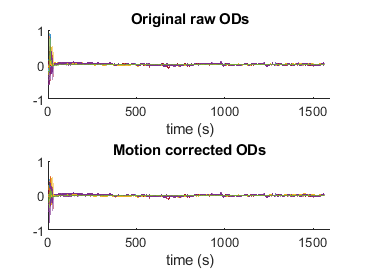

t = dod.time;
y = dod.dataTimeSeries;

yMC = dodMC.dataTimeSeries;
tstart = acquired.stim(1,2).data(1);

% channels to plot 
channels = 1:size(y, 2);
figure; 
ax1 = subplot(211); hold on
for iCh = 1:length(channels)
    plot(t, detrend(y(:, iCh)));
    xlabel('time (s)')
end
title('Original raw ODs')
ax2 = subplot(212); hold on
for iCh = 1:length(channels)
    plot(t, detrend(yMC(:, iCh)));
    xlabel('time (s)')
end
title('Motion corrected ODs')
linkaxes([ax1, ax2])

% xlim([tstart max(t)]);

#### OD to Concentrations 

Once our data has been corrected for motion, we proceed to obtain the concentration changes in O2Hb and HHb by means of the Modified Lambert-Beer Law, as follows:

dhb  = hmrR_OD2Conc(dodMC, acquired.probe, [1,1]);

Data visualization

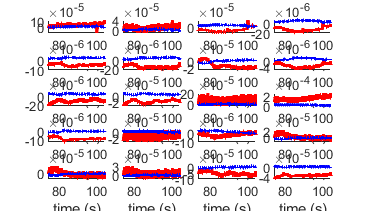

% Extract plot data from output of last function 
t = dhb.time;
y = dhb.GetDataTimeSeries('reshape');

% fs = 1/diff(dhb.time(1:2)); % sampling frequency
tstart = acquired.stim(1,2).data(1);
tend = tstart + 30;

% Hb type - {1 -> HbO,  2 -> HbR,  3 -> HbT}
hbType   = [1, 2];

% channels to plot 
channels = 1:size(y, 3);
color_map = {'r', 'b', 'green'};
figure;
axes_array = [];
p = get(gcf, 'position');
set(gcf, 'position', [p(1), p(2), p(3)*1.3, p(4)]);
for iHb = 1:length(hbType)
    for iCh = 1:length(channels)
        axes_array = [axes_array subplot(5,4,iCh)]; hold on
        plot(t, detrend(y(:, hbType(iHb), channels(iCh))),...
            color_map{iHb}, 'LineWidth', 1.5);
        xlabel('time (s)')
        xlim([tstart tend]);
    end
end
linkaxes(axes_array, 'x')

#### Bandpass filter 

dhbFilt = hmrR_BandpassFilt(dhb, 0.01, 0.50);

#### Block average

Now we are interested in performing a block average over trials belonging to our fingertapping task. To do so, we first have a look at the stimulus information contained out *acquired *Snirf data structure.

fprintf('Event type:\n- %s\n- %s\n- %s', acquired.stim(1).name, acquired.stim(2).name,acquired.stim(3).name)

Event type:
- Fingertapping
- Instructions
- Rest period

We select stim 1, corresponding to the fingertapping task, and choose a prestimulus and poststimulus time of 5 and 30 seconds, respectively. We then proceed to average over trials per channel as follows:

tPre = -5;
tPost = 30;
dhbAvg = hmrR_BlockAvg(dhbFilt, acquired.stim(1), [tPre, tPost]);

% Extract plot data from output of last function 
tAvg = dhbAvg.time;
yAvg = dhbAvg.GetDataTimeSeries('reshape');

We then plot the resulting average

-  on O2Hb and HHb signals

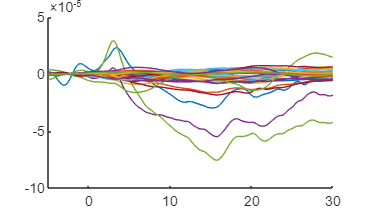

PlotData(tAvg, yAvg, hbType, channels);

- on O2Hb signals

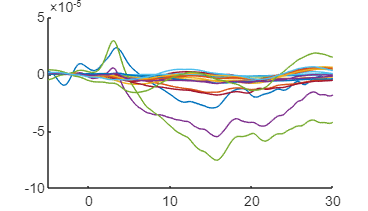

PlotData(tAvg, yAvg, 1, channels);

- on HHb signals

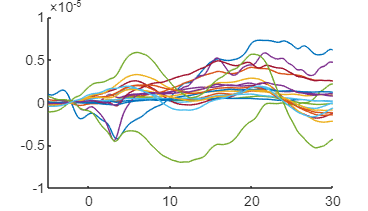

PlotData(tAvg, yAvg, 2, channels);